# Importar dados do arquivo CSV

dados = readtable('dados.csv');

## Extrair tempo, velocidade e potência

tempo = dados.Tempo;
velocidade = dados.Velocidade;

## Calcular a diferença de velocidade

delta_velocidade = diff(velocidade);

## Calcular a diferença de tempo

delta_tempo = diff(tempo);

## Calcular a aceleração como a taxa de variação da velocidade

aceleracao = delta_velocidade ./ delta_tempo;

## Calcular a força de tração usando a segunda lei de Newton

massa = 1000; % kg (ajuste de acordo com a massa do veículo)
forca_tracao = massa * aceleracao;

## Calcular a potência do motor

potencia = forca_tracao .* velocidade(2:end); % Ignorando o primeiro ponto devido à diferenciação

## Plote os resultados

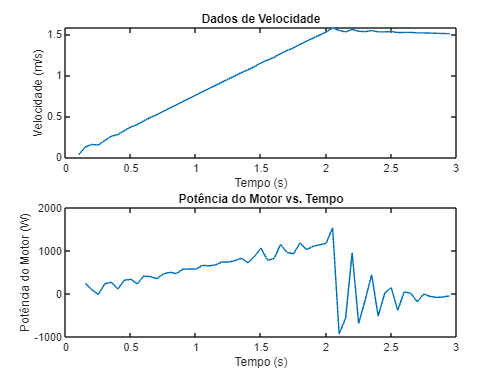

figure;
subplot(2, 1, 1);
plot(tempo, velocidade);
xlabel('Tempo (s)');
ylabel('Velocidade (m/s)');
title('Dados de Velocidade');

subplot(2, 1, 2);
plot(tempo(2:end), potencia);
xlabel('Tempo (s)');
ylabel('Potência do Motor (W)');
title('Potência do Motor vs. Tempo');

## Análise de como a potência do motor varia com a velocidade

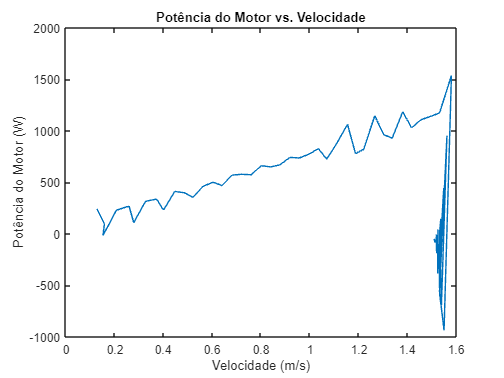

figure;
plot(velocidade(2:end), potencia);
xlabel('Velocidade (m/s)');
ylabel('Potência do Motor (W)');
title('Potência do Motor vs. Velocidade');

## Calcular a força de resistência ao rolamento (modelo simplificado)

Assumindo que a resistência ao rolamento é uma constante (Crr)

Crr = 0.02;
forca_rolamento = Crr * massa * 9.81 * ones(size(velocidade(2:end)));

## Calcular a força de resistência do ar (modelo simplificado)

Assumindo que a força de arrasto é proporcional ao quadrado da velocidade (0.5 * rho * Cd * A * v^2)

CdA = 0.3;
densidade_ar = 1.225; % Densidade do ar (ajuste de acordo com as condições)
forca_arrasto = 0.5 * CdA * densidade_ar * (velocidade(2:end).^2);

## Calcular a potência total necessária para vencer as resistências

potencia_total = potencia + forca_rolamento .* velocidade(2:end) + forca_arrasto .* velocidade(2:end);

## Ajuste do modelo (parâmetros Crr e CdA)

modelo_ajustado = fitlm(velocidade(2:end), potencia_total);

## Parâmetros do modelo ajustado

coeficientes = modelo_ajustado.Coefficients.Estimate;
coeficiente_Crr = coeficientes(1)

coeficiente_Crr = 470.2415

coeficiente_CdA = coeficientes(2)

coeficiente_CdA = 141.5608

## Exibir os parâmetros do modelo ajustado

disp('Parâmetros do modelo ajustado:');

Parâmetros do modelo ajustado:


disp(['Coeficiente de Resistência ao Rolamento (Crr): ' num2str(coeficiente_Crr)]);

Coeficiente de Resistência ao Rolamento (Crr): 470.2415


disp(['Coeficiente de Arrasto x Área Frontal (CdA): ' num2str(coeficiente_CdA)]);

Coeficiente de Arrasto x Área Frontal (CdA): 141.5608


## Ajuste de um modelo linear

modelo_linear = fitlm(velocidade(2:end), potencia);

## Parâmetros do modelo ajustado

coeficientes = modelo_linear.Coefficients.Estimate

coeficientes =   470.4756
  -55.1846


intercept = coeficientes(1);
coeficiente_linear = coeficientes(2)

coeficiente_linear = -55.1846

## Exibir os parâmetros do modelo linear

disp('Parâmetros do modelo linear ajustado:');

Parâmetros do modelo linear ajustado:


disp(['Intercept (Potência no repouso): ' num2str(intercept) ' W']);

Intercept (Potência no repouso): 470.4756 W


disp(['Coeficiente Linear (Variação de Potência por m/s): ' num2str(coeficiente_linear) ' W/(m/s)']);

Coeficiente Linear (Variação de Potência por m/s): -55.1846 W/(m/s)


## Plotagem do modelo ajustado

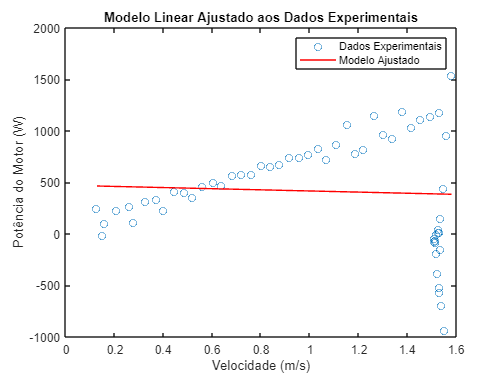

velocidade_ajustada = linspace(min(velocidade(2:end)), max(velocidade(2:end)), 100);
potencia_ajustada = intercept + coeficiente_linear * velocidade_ajustada;

figure;
plot(velocidade(2:end), potencia, 'o', 'DisplayName', 'Dados Experimentais');
hold on;
plot(velocidade_ajustada, potencia_ajustada, 'r-', 'DisplayName', 'Modelo Ajustado');
xlabel('Velocidade (m/s)');
ylabel('Potência do Motor (W)');
legend;
title('Modelo Linear Ajustado aos Dados Experimentais');

## Definir uma função de modelo para calcular a potência total

modelo = @(parametros, velocidade) calcular_potencia_total(parametros, velocidade, massa, tempo);

## Suposições iniciais para os parâmetros Crr e CdA

parametros_iniciais = [0.01, 0.3];

## Realizar otimização para ajustar os parâmetros

parametros_otimizados = lsqcurvefit(modelo, parametros_iniciais, velocidade(2:end), potencia);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


## Parâmetros otimizados

Crr_otimizado = parametros_otimizados(1)

Crr_otimizado = 0.1252

CdA_otimizado = parametros_otimizados(2)

CdA_otimizado = -757.8803

## Exibir os parâmetros otimizados

disp('Parâmetros otimizados:');

Parâmetros otimizados:


disp(['Coeficiente de Resistência ao Rolamento (Crr): ' num2str(Crr_otimizado)]);

Coeficiente de Resistência ao Rolamento (Crr): 0.12517


disp(['Coeficiente de Arrasto x Área Frontal (CdA): ' num2str(CdA_otimizado)]);

Coeficiente de Arrasto x Área Frontal (CdA): -757.8803


## Calcular a força de resistência ao rolamento (modelo simplificado)

forca_rolamento = Crr_otimizado * massa * 9.81 * ones(size(velocidade));

## Calcular a força de resistência do ar (modelo simplificado)

forca_arrasto = 0.5 * CdA_otimizado * densidade_ar * (velocidade.^2);

## Calcular a potência total necessária para vencer as resistências

potencia_total_otimizada = forca_rolamento .* velocidade + forca_arrasto .* velocidade;

## Plote os resultados

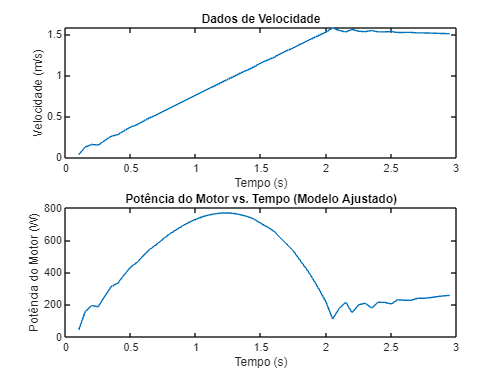

figure;
subplot(2, 1, 1)
plot(tempo, velocidade);
xlabel('Tempo (s)');
ylabel('Velocidade (m/s)');
title('Dados de Velocidade');

subplot(2, 1, 2)
plot(tempo, potencia_total_otimizada);
xlabel('Tempo (s)');
ylabel('Potência do Motor (W)');
title('Potência do Motor vs. Tempo (Modelo Ajustado)');


g = 9.81;        % Aceleração devido à gravidade
referencia_velocidade = 20;  % Velocidade de referência em m/s

## Controlador PID

Kp = 10;     % Ganho proporcional
Ki = 0.01;   % Ganho integral
Kd = 1;      % Ganho derivativo
integral = 0;
anterior_erro = 0;

## Variáveis de controle

tempo_simulacao = 3;  % Tempo de simulação em segundos
tempo = linspace(0, tempo_simulacao, 1000);
velocidade_atual = zeros(size(tempo));
aceleracao_atual = zeros(size(tempo));
erro_anterior = 0;

## Velocidade de referência constante

velocidade_referencia = referencia_velocidade * ones(size(tempo));
aceleracao_referencia = zeros(size(tempo)); % A aceleração de referência é zero

## Simulação do controle

for i = 1:length(tempo)
    % Medida da velocidade (pode ser obtida na prática com sensores)
    velocidade_medida = velocidade_atual(i) + normrnd(0, 0.1);  % Adiciona ruído à medição

    % Erro de velocidade
    erro = referencia_velocidade - velocidade_medida;

    % Ação de controle do PID
    integral = integral + erro;
    derivativo = erro - erro_anterior;

    aceleracao = Kp * erro + Ki * integral + Kd * derivativo;

    % Modelagem da dinâmica do veículo
    forca_rolamento = Crr * massa * g;
    forca_arrasto = 0.5 * CdA * densidade_ar * (velocidade_atual(i) ^ 2);

    % Equação de movimento
    forca_resultante = massa * aceleracao + forca_rolamento + forca_arrasto;
    velocidade_atual(i+1) = velocidade_atual(i) + (forca_resultante / massa) * (tempo(2) - tempo(1));
    aceleracao_atual(i) = aceleracao;

    erro_anterior = erro;
end

## Plote os resultados

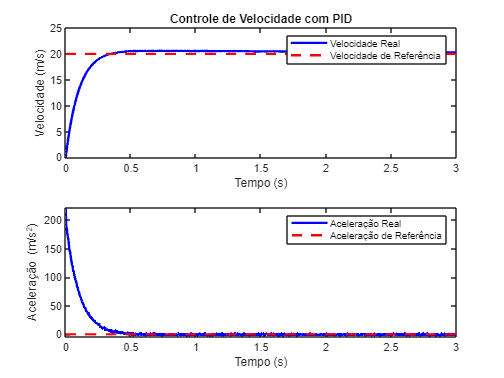

figure;
subplot(2, 1, 1)
plot(tempo, velocidade_atual(1:end-1), 'b', 'LineWidth', 2)
hold on
plot(tempo, velocidade_referencia, 'r--', 'LineWidth', 2)
xlabel('Tempo (s)')
ylabel('Velocidade (m/s)')
title('Controle de Velocidade com PID')
legend('Velocidade Real', 'Velocidade de Referência')

subplot(2, 1, 2)
plot(tempo, aceleracao_atual, 'b', 'LineWidth', 2)
hold on
plot(tempo, aceleracao_referencia, 'r--', 'LineWidth', 2)
xlabel('Tempo (s)')
ylabel('Aceleração (m/s^2)')
legend('Aceleração Real', 'Aceleração de Referência')

## Função para calcular a potência total com base nos parâmetros Crr e CdA

function potencia_total = calcular_potencia_total(parametros, velocidade, massa, tempo)
    Crr = parametros(1);
    CdA = parametros(2);
    
    % Calcular a força de resistência ao rolamento (modelo simplificado)
    forca_rolamento = Crr * massa * 9.81 * ones(size(velocidade));

    % Calcular a força de resistência do ar (modelo simplificado)
    forca_arrasto = 0.5 * CdA * 1.225 * (velocidade.^2);

    % Calcular a potência total necessária para vencer as resistências
    potencia_total = forca_rolamento .* velocidade + forca_arrasto .* velocidade;
end